% Load CSV file
data = readtable('synthetic_wind_storage_data_10000.csv');


% Extract columns
time = data{:, 1};  % Time in seconds
frequency_deviation = data{:, 4};  % Frequency Deviation (Hz)
battery_soc = data{:, 5};  % Battery SOC (%)

% Compute df/dt (Rate of change of frequency)
df_dt = [0; diff(frequency_deviation) ./ diff(time)];  % Numerical derivative

% Define target output (ESS Power Command) - Replace with actual data
% If you don't have actual power command data, create a dummy function
ess_power_command = -0.1 * frequency_deviation + 0.05 * df_dt + 0.2 * (50 - battery_soc);

% Prepare input-output dataset
training_data = [frequency_deviation, df_dt, battery_soc, ess_power_command];

% Save to MATLAB workspace
assignin('base', 'training_data', training_data);

% Generate an initial fuzzy system with 5 membership functions
fis = genfis1(training_data, 5, 'gbellmf'); 


% Save the initial fuzzy model
writeFIS(fis, 'initial_fis.fis');

% Load the initial FIS
fis = readfis('initial_fis.fis');
ANFIS info:
	Number of nodes: 286
	Number of linear parameters: 500
	Number of nonlinear parameters: 45
	Total number of parameters: 545
	Number of training data pairs: 10000
	Number of checking data pairs: 0
	Number of fuzzy rules: 125


Start training ANFIS ...

% Train the FIS using ANFIS
[trained_fis, error] = anfis(training_data, fis, 100);  % 100 training epochs


ANFIS info:
	Number of nodes: 286
	Number of linear parameters: 500
	Number of nonlinear parameters: 45
	Total number of parameters: 545
	Number of training data pairs: 10000
	Number of checking data pairs: 0
	Number of fuzzy rules: 125


Start training ANFIS ...

1 	 0.000241615
2 	 0.000226282
3 	 0.000206947
4 	 0.000188966
Step size increases to 0.011000 after epoch 5.
5 	 0.000182377
6 	 0.000202569
7 	 0.000247681
8 	 0.000217925
9 	 0.00023424
Step size decreases to 0.009900 after epoch 10.
10 	 0.000215254
11 	 0.000211823
12 	 0.000172955
13 	 0.000204372
14 	 0.000180371
15 	 0.000183102
16 	 0.000191657
17 	 0.000168833
18 	 0.000205697
Step size decreases to 0.008910 after epoch 19.
19 	 0.000175228
20 	 0.000187551
21 	 0.000188913
22 	 0.000160538
23 	 0.000131344
24 	 0.000169186
25 	 0.000159823
26 	 0.000150746
27 	 0.000170094
28 	 0.000169761
29 	 0.000139472
30 	 0.000124764
31 	 0.000147437
32 	 0.000165698
33 	 0.000126357
34 	 0.000137074
35 	 0.000143876
36 	 0


% Save the trained FIS
writeFIS(trained_fis, 'pfnn_trained.fis');

figure;
plot(ess_power_command, 'b'); hold on;
plot(evalfis(training_data(:, 1:3), trained_fis), 'r--');

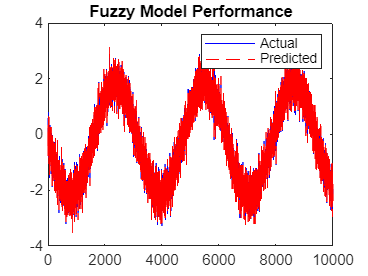

legend('Actual', 'Predicted');
title('Fuzzy Model Performance');